clear all
close all
addpath('..\common')
myplot=@(x,colr) plot3(x(:,1),x(:,2),x(:,3),colr);

dep_path = '..\common\face\';

%相机内参
% Kc=[475.722, 0.0, 310.241
%     0.0, 475.722, 246.003
%     0.0,  0.0,    1.0];

奥比RGBD相机采集图像对

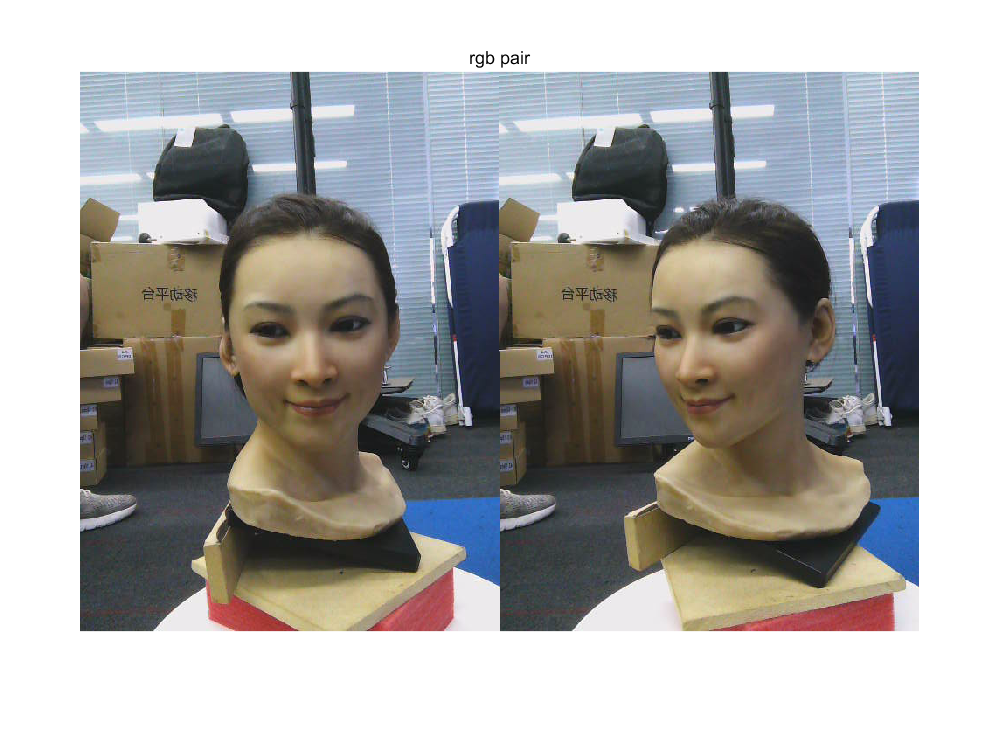

Kc=[537.9 0.0 222.596
0.0 537.9 321.346
0.0 0.0 1.0];

 
% 深度序列
im{1} = imread([dep_path,'0_rgb.png']);
im{2} = imread([dep_path,'43_rgb.png']);

figure(1)
imshow([im{1},im{2}]),title('rgb pair')


dp{1} = imread([dep_path,'0.png']);
dp{2} = imread([dep_path,'43.png']);

%remove background  
thd = 500;
dp{1}=single(dp{1}).*(dp{1}<thd);
dp{2}=single(dp{2}).*(dp{2}<thd);

figure(2)
imshow([dp{1},dp{2}],[]),title('depth pair')

计算法向量

% V and N
[vts{1},nvs{1}] = dp2vn( single(dp{1}),Kc,1 );
[vts{2},nvs{2}] = dp2vn( single(dp{2}),Kc,1 );

initRT = eye(4); 

% align 2 PCs by initRT
vt1 = apply_rt(vts{1},initRT);
R=initRT; R(1:3,4)=0;
nv1 = apply_rt(nvs{1},R);

figure(11),hold on
myplot(vts{2},'r.'),axis equal
myplot(vt1,'b.'),view(0,-80),title('Before ICP')
legend('v2','v1')

point-plane error ICP

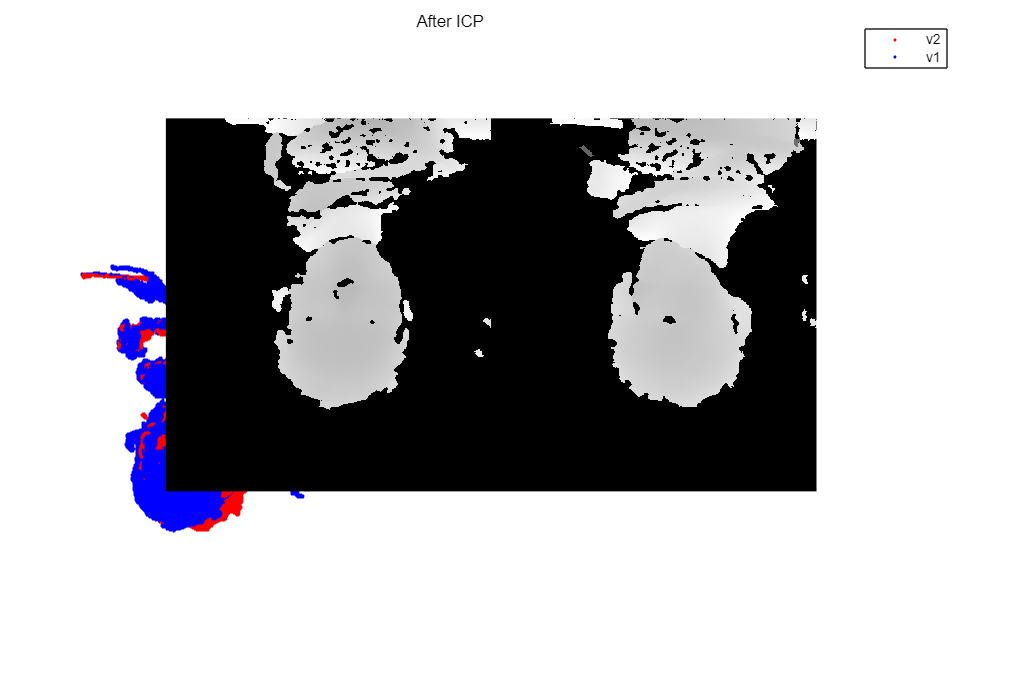

% ICP goes here ...
ICP_option = struct( 'th_reject',20, 'Round', 20 );
[dRT,Ra,Ta,pv] = ICP_point2plane(vt1,nv1,vts{2},nvs{2},ICP_option);
RT = dRT*initRT;

% align 2 PCs by RT
vt1 = apply_rt(vts{1},RT);
R=RT;R(1:3,4)=0;
nv1 = apply_rt(nvs{1},R);

figure(12),
myplot(vts{2},'r.'),hold on
myplot(vt1,'b.')
axis equal,view(0,-80), title('After ICP')
legend('v2','v1')


write_xyz_vn('aligned.xyz',[vt1;vts{2}],[nv1;nvs{2}])
return

function po = apply_rt(p,M)
zv = ones(size(p,1),1);
po = [p,zv]*M';
po = po(:,1:3);
end